# Load data

%% Data has been pre-loaded into matlab and converted into a .mat data struct with fields: Fs, EEG
uiopen(".mat");

## Extract Data

EEG_fp1 = Data.EEG(:,1);
EEG_fp2 = Data.EEG(:,2);
EEG_c1 = Data.EEG(:,3); % If available
EEG_c2 = Data.EEG(:,4); % If available
Fs = Data.Fs;

## Plot raw EEG data

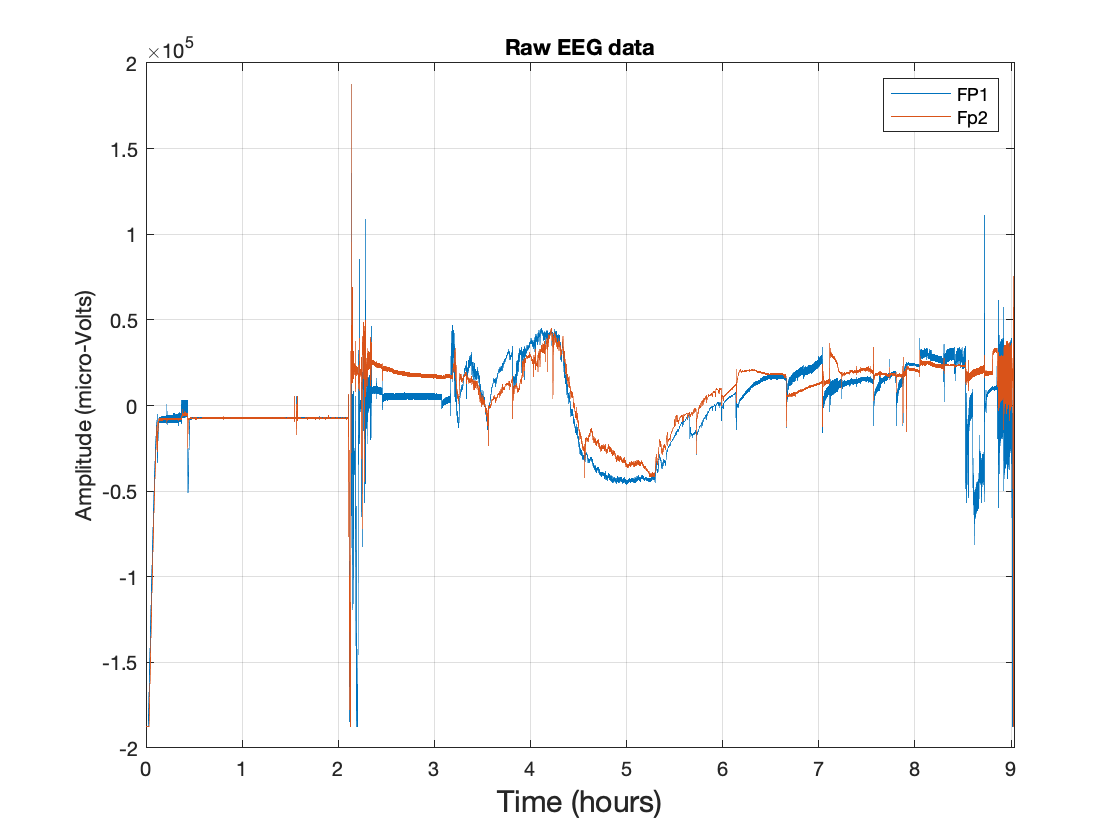

t = (1:1:length(EEG_fp1))/Fs/3600;
figure;
plot(t,EEG_fp1);
hold on
plot(t,EEG_fp2);
% hold on
% plot(EEG_c1(2150000:7670000));
% hold on
% plot(EEG_c2(2150000:7670000));
xlabel("Time (hours)", "FontSize",15);
ylabel("Amplitude (micro-Volts)");
title("Raw EEG data");
xlim([0,length(EEG_fp1)/Fs/3600])
legend("FP1", "Fp2");
grid on
hold off

## Resize the dataset

% trim the first and last part of the data off and make the size divisible by the epoch size
EEG_fp1 = EEG_fp1(2150001:7670000); %number picked based on the raw data plot
EEG_fp2 = EEG_fp2(2150001:7670000); 
t = (1:1:length(EEG_fp1))/Fs/3600;

## Bandpass filter

EEG_fp1 = eeg_filter(EEG_fp1, 0.1, 40, Fs);
EEG_fp2 = eeg_filter(EEG_fp1, 0.1, 40, Fs);

## Data after filtering

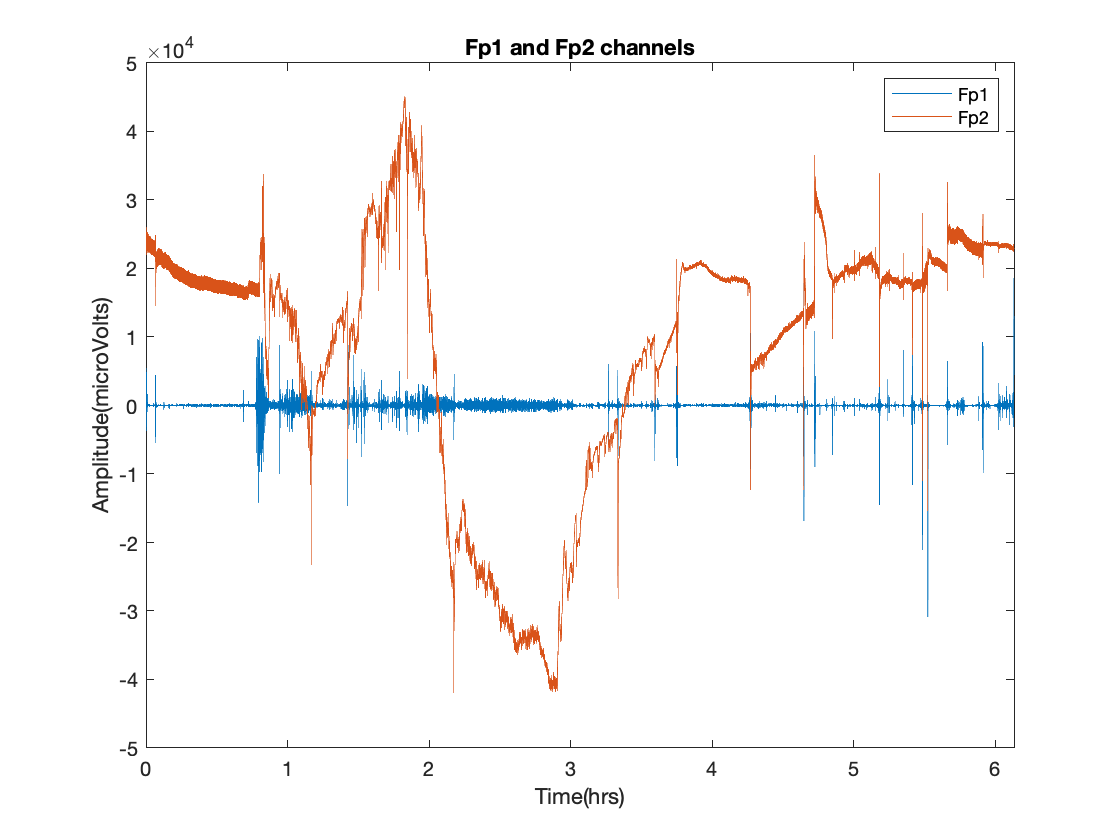

figure;
t = (1:1:length(EEG_fp1))/Fs/3600;
% subplot(2,1,1);
plot(t, EEG_fp1);
hold on
plot(t,EEG_fp2);
hold off
xlabel("Time(hrs)");
ylabel("Amplitude(microVolts)");
legend("Fp1", "Fp2")
title("Fp1 and Fp2 channels");
xlim([0,length(EEG_fp1)/Fs/3600]);

% subplot(2,1,2)
% plot(1:length(EEG_fp), EEG_fp);
% xlabel("Time(hrs)");
% ylabel("Amplitude(microVolts)");
% title("Synchronized Fp channel");
% xlim([0,length(EEG_fp)/Fs/3600]);
% title("Time Domain");
% subplot(2,1,2);
% [p,f] = pspectrum(EEG_fp1,Fs,"power","FrequencyLimits",[0,40]);
% plot(f, p);
% hold on
% [p,f] = pspectrum(EEG_fp2,Fs,"power","FrequencyLimits",[0,40]);
% plot(f, p);
% hold off
% ylabel('Power(dB)');
% grid on
% title('Power Spectrum');
% xlim([0,40]);

## Segmentation

epoch_size = 7500; % each epouch has 30 sec of data
EEG_fp1_m = reshape(EEG_fp1,epoch_size,[]);
EEG_fp2_m = reshape(EEG_fp2,epoch_size,[]);
[~, L] = size(EEG_fp1_m);

## Artifact removal

EEG_fp_m = zeros(epoch_size, L);
for i= 1:1:L
    if std(EEG_fp1_m(:,i))<std(EEG_fp2_m(:,i))
        EEG_fp_m(:,i) = EEG_fp1_m(:,i);
    else
        EEG_fp_m(:,i) = EEG_fp2_m(:,i);
    end
end
EEG_fp = reshape(EEG_fp_m,[],1)';
EEG_fp_m = EEG_fp_m';

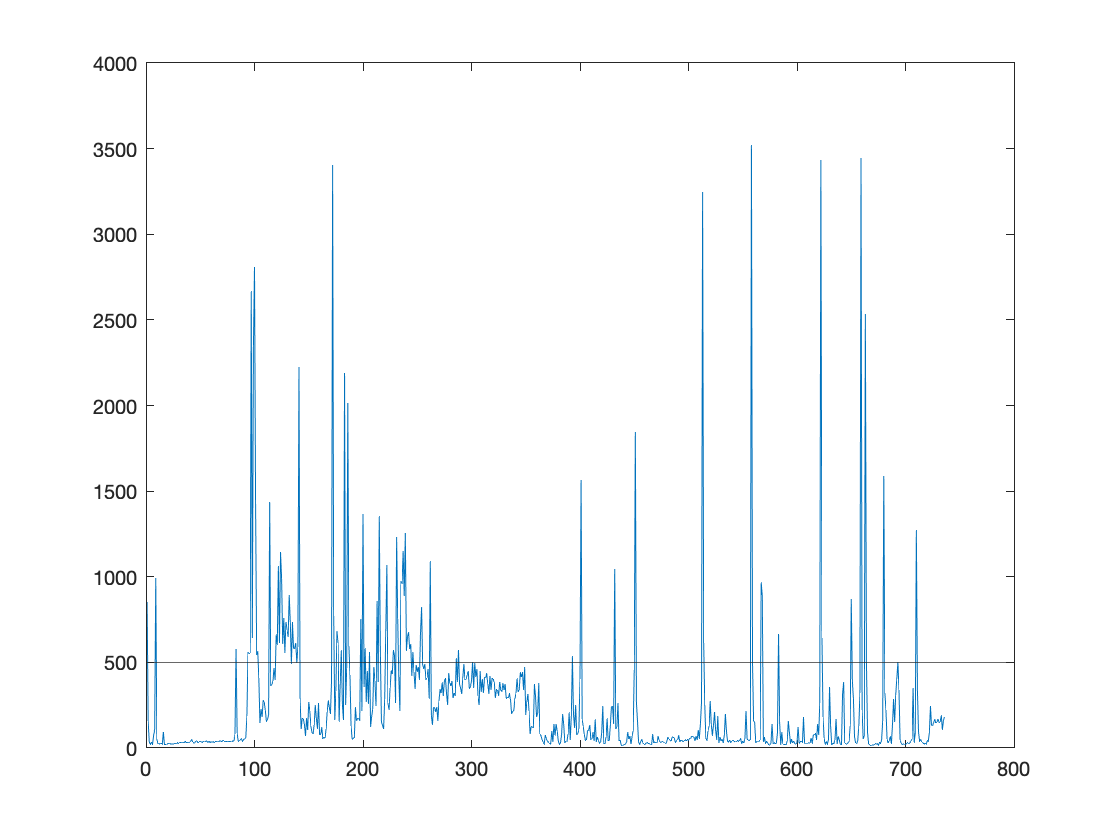

figure
plot(std(EEG_fp_m,[],2));
yline(500);

arti = (std(EEG_fp_m,[],2) > 500);

## Artifact removal - S transform

EEG_m = [];
% this process takes very long so we only performed it on certain epochs (arti)
for k = 1: L
    if (arti(k) == 1)
        p = stran(EEG_fp_m(k,:));
        % Threshold
        Thres = mean(abs(p))+2*std(abs(p));
        mf = 0.1;
        [m,n] = size(p);
        for i = 1:m
            for j = 1:n
                if (abs(p(i,j))>= Thres(1,j))
                    p(i,j) = p(i,j) * mf;
                end
            end
        end
        % inverse FT
        EEG_m(k,:) = istran(p);
    end
end

EEG_fp_m(arti,:) = EEG_m(arti,2:end-1);

EEG = reshape(EEG_fp_m',[],1)';

## Data Visualization

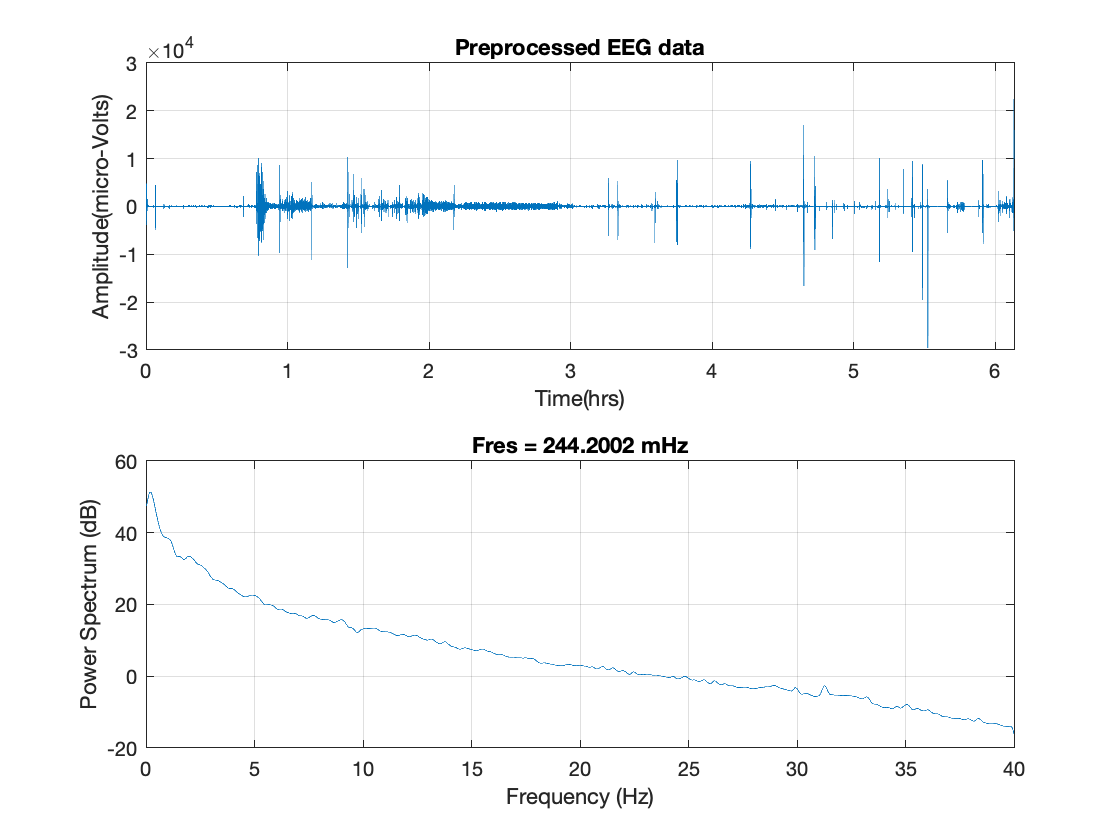

figure;
t = (1:1:length(EEG))/Fs/3600;
subplot(2,1,1);
plot(t, EEG);
xlim([0,length(EEG)/Fs/3600]);
% ylim([-6000,4000]);
xlabel("Time(hrs)");
ylabel("Amplitude(micro-Volts)");
title("Preprocessed EEG data");
grid on
subplot(2,1,2);
pspectrum(EEG,Fs,"power","FrequencyLimits",[0,40]);

figure
pspectrum(EEG,Fs,'spectrogram','FrequencyLimits',[0, 40], "FrequencyResolution", 0.5)

Error using pspectrum>extractTypeAndNameValuePairs (line 1054)
Name-value inputs must come in pairs.

Error in pspectrum>parseAndValidateInputs (line 732)
opts = extractTypeAndNameValuePairs(inputCell, opts);

Error in 

title("Spectrogram");

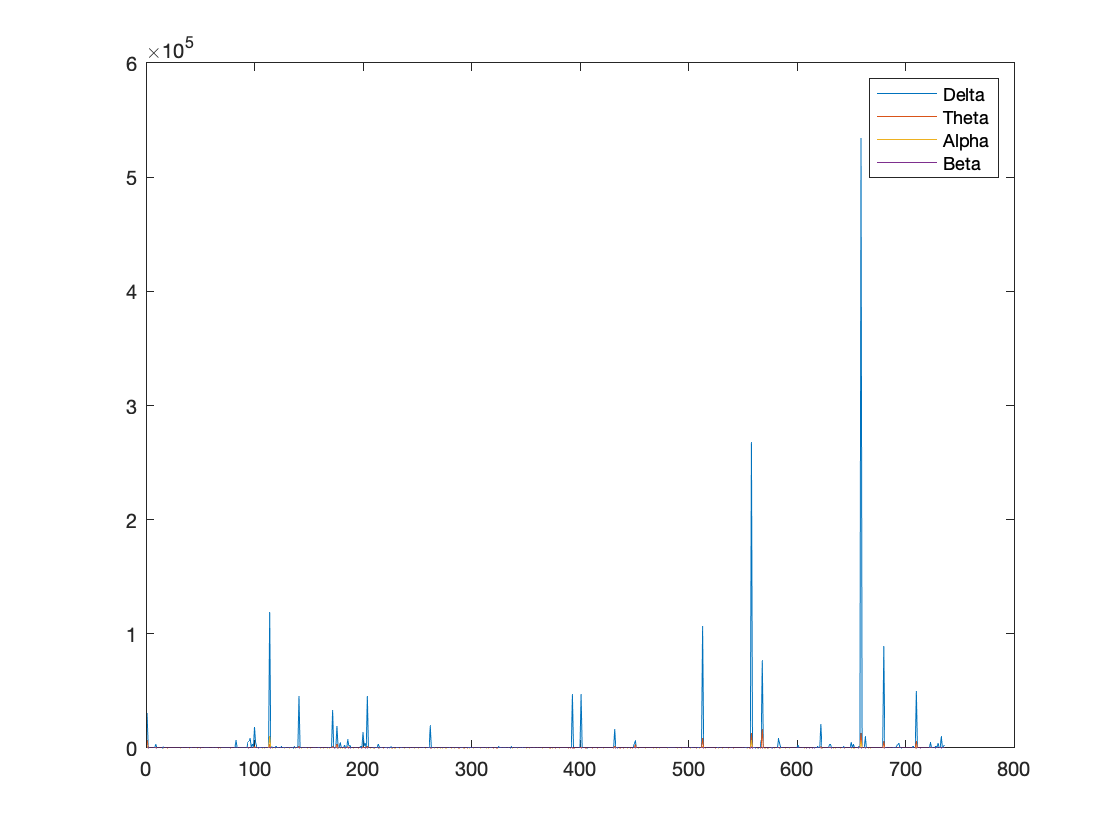

[s, f, t, p] = spectrogram(EEG, epoch_size, 0, (1:0.5:40), Fs,'yaxis');
del = sum(p(1:8,:))/8;
the = sum(p(8:16,:))/8;
alp = sum(p(16:24,:))/8;
bet = sum(p(24:60,:))/36;
figure;
plot(del);
hold on
plot(the);
hold on
plot(alp);
hold on
plot(bet);
legend("Delta", "Theta", "Alpha", "Beta");

## wavelet analysis

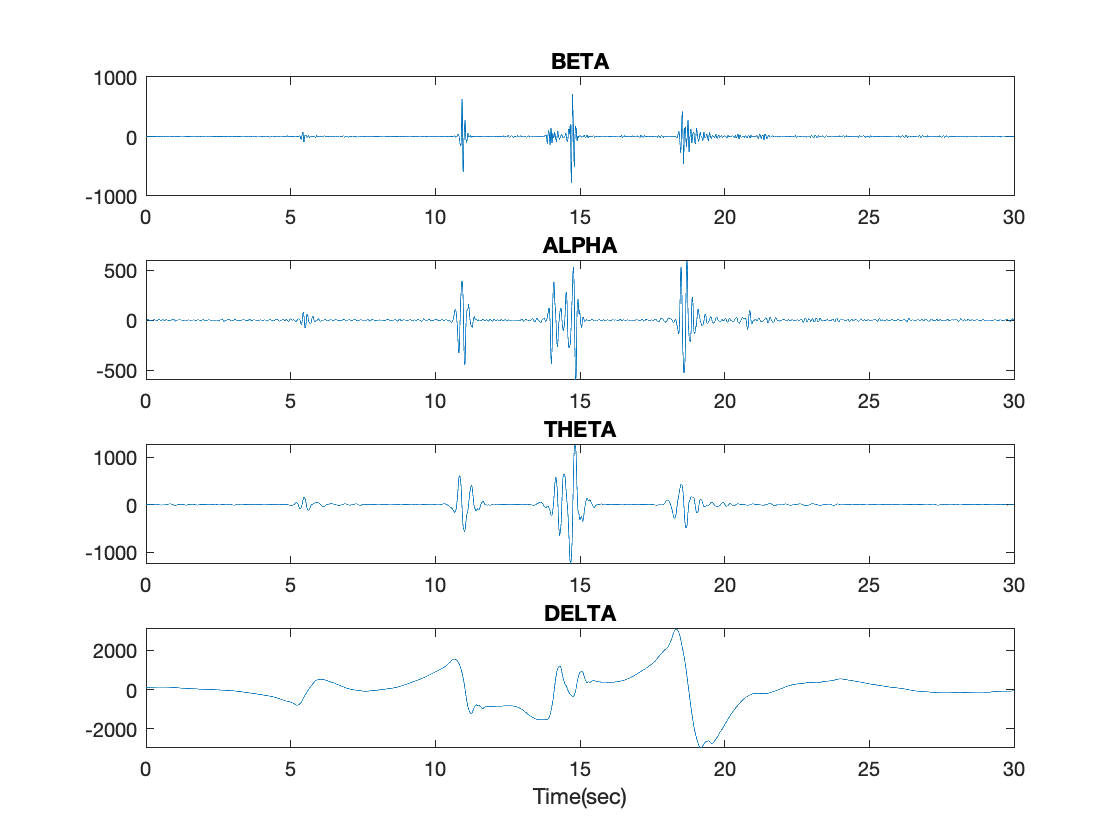

epo = 251;
s = EEG_fp_m(200,:);
N = length(s);

% Define the wavelet's name and the level for decomposition
waveletName='db5';
level=6;
% Multilevel 1-D wavelet decomposition for channel 0
[c,l]=wavedec(s,level,waveletName);
% Beta Alpha Theta
[~,~,~,cd4,cd5,cd6] = detcoef(c,l,[1 2 3 4 5 6]);
ca6 = appcoef(c,l,waveletName,6); % DELTA
 
% Reconstruct single branch from 1-D wavelet coefficients
 D4 = wrcoef('d',c,l,waveletName,4); % BETA 
 D5 = wrcoef('d',c,l,waveletName,5); % ALPHA 
 D6 = wrcoef('d',c,l,waveletName,6); % THETA 
 A6 = wrcoef('a',c,l,waveletName,6); % DELTA

 t = 1/Fs:1/Fs:epoch_size/Fs;
 
figure;
           
Beta = D4;
subplot(4,1,1);
plot(t, Beta);
title('BETA');
                     
Alpha = D5;
subplot(4,1,2);
plot(t,Alpha); 
title('ALPHA'); 
            
Theta = D6;
subplot(4,1,3); 
plot(t,Theta);
title('THETA');
            
Delta = A6;
subplot(4,1,4);
plot(t,Delta);
title('DELTA');
xlabel("Time(sec)");

sig = EEG_fp_m;
[L,~] = size(sig);
pAlpha = zeros(1,L);
pBeta = zeros(1,L);
pTheta = zeros(1,L);
pDelta = zeros(1,L);
del_amp = zeros(1,L);
waveletName='db5';
level=6;
for epo = 1:1:L
    s = sig(epo,:);
    % Multilevel 1-D wavelet decomposition
    [c,l] = wavedec(s,level,waveletName);
    % Reconstruct single branch from 1-D wavelet coefficients
    Beta = wrcoef('d',c,l,waveletName,4); % BETA 
    Alpha = wrcoef('d',c,l,waveletName,5); % ALPHA 
    Theta = wrcoef('d',c,l,waveletName,6); % THETA 
    Delta = wrcoef('a',c,l,waveletName,6); % DELTA
    
    del_amp(1,epo) = mean(abs(Delta));
    
    pDelta(1,epo) = pow2db(bandpower(Delta));
    pTheta(1,epo) = pow2db(bandpower(Theta));
    pAlpha(1,epo) = pow2db(bandpower(Alpha));
    pBeta(1,epo) = pow2db(bandpower(Beta));
end

spDelta = smooth(pDelta,0.01);
spTheta = smooth(pTheta,0.01);
spAlpha = smooth(pAlpha,0.01);
spBeta = smooth(pBeta,0.01);
del_amp = smooth(del_amp,0.01);

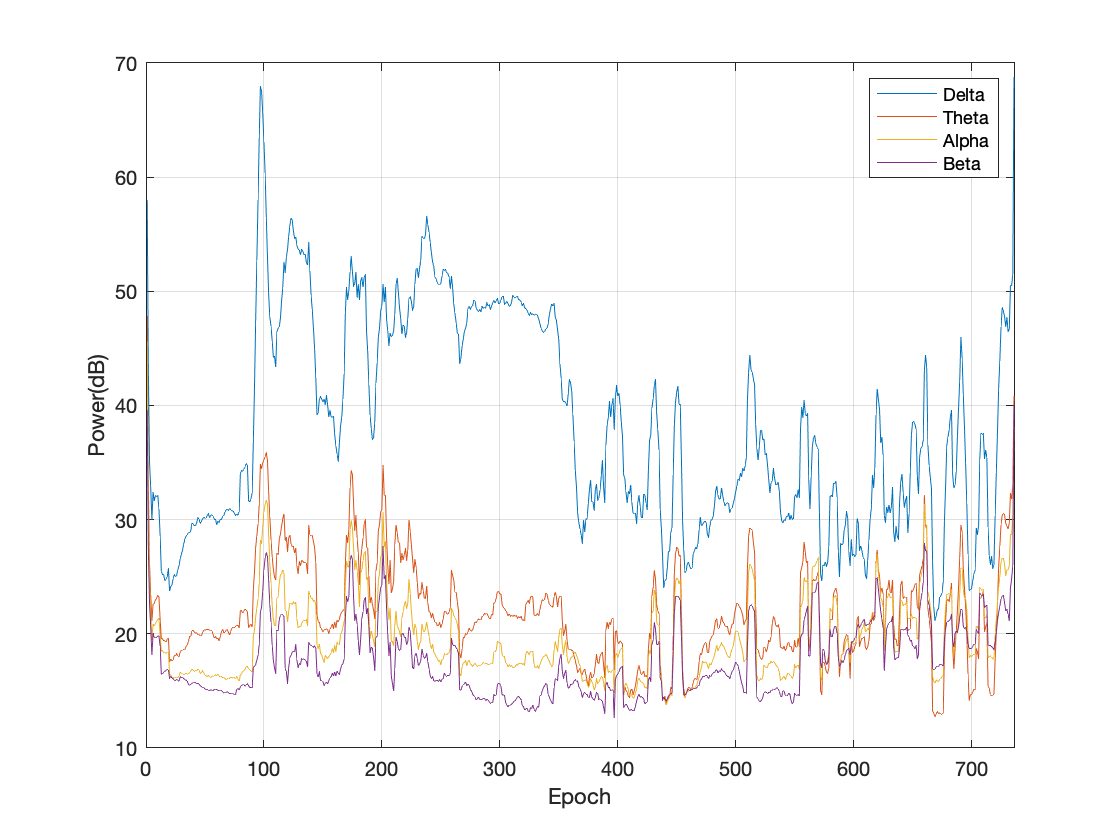

tL = (1:1:L);
figure;
plot(tL, spDelta);
hold on
plot(tL, spTheta);
hold on
plot(tL, spAlpha);
hold on
plot(tL, spBeta);
legend("Delta", "Theta", "Alpha", "Beta");
xlabel("Epoch");
ylabel("Power(dB)");
xlim([0, L])
grid on
hold off

ThD = mean(spDelta) + std(spDelta);
ThB = mean(spBeta) + std(spBeta)/2;
ThA = mean(spAlpha) + std(spAlpha)/2;
class = [];
class_psg = [];
for i = 1: L
    if (spDelta(i) >= ThD && i > L*0.1 && i < L*0.9) 
        class(i) = 2;
    elseif (spBeta(i) >= ThB)
        class(i) = 0;
    else
        class(i)=1;
    end
%     if (Data.Hyp(i) == 3)
%         class_psg(i) = 2;
%     elseif (Data.Hyp(i) == 0)
%         class_psg(i) = 0;
%     else
%         class_psg(i) = 1;
%     end
end

Deep = 0;
Awake = 0;
for i = 1: L
    if class(i) == 2
        Deep = Deep+1;
    end
    if class(i) == 0
        Awake = Awake + 1;
    end
end

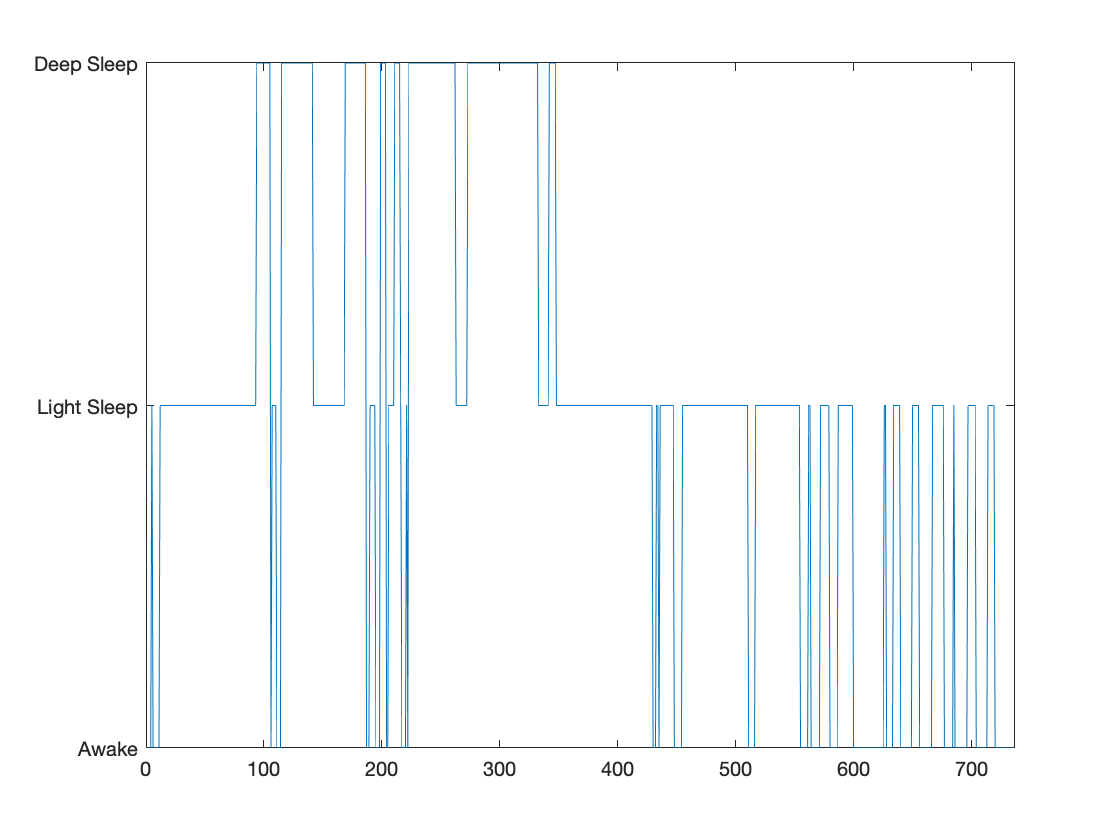

figure;
plot(tL,class);
xlim([0,L]);
yticks([0 1 2]);
yticklabels({'Awake', 'Light Sleep', 'Deep Sleep'});

% hold on
% plot(tL,class_psg,"Linewidth", 2);
% legend("Experimental", "Theoritical");

err = 0;
TP = 0;
FP = 0;
FN = 0;
TN = 0;
for i = 1: L
    if (class(i) ~= class_psg(i))
        err = err+1;
    end
    if (class_psg(i) == 2)
        if class(i) == 2L
            TP = TP+1;
        else
            FN = FN+1;
        end
    else
        if class(i) == 2
            FP = FP+1;
        else
            TN = TN+1;
        end
    end
end
err/L

ans = 0.3429